%~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
%
% Examine_TIWE_Data
%
%
%
% 10/21/16 - A.Pickering
%~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

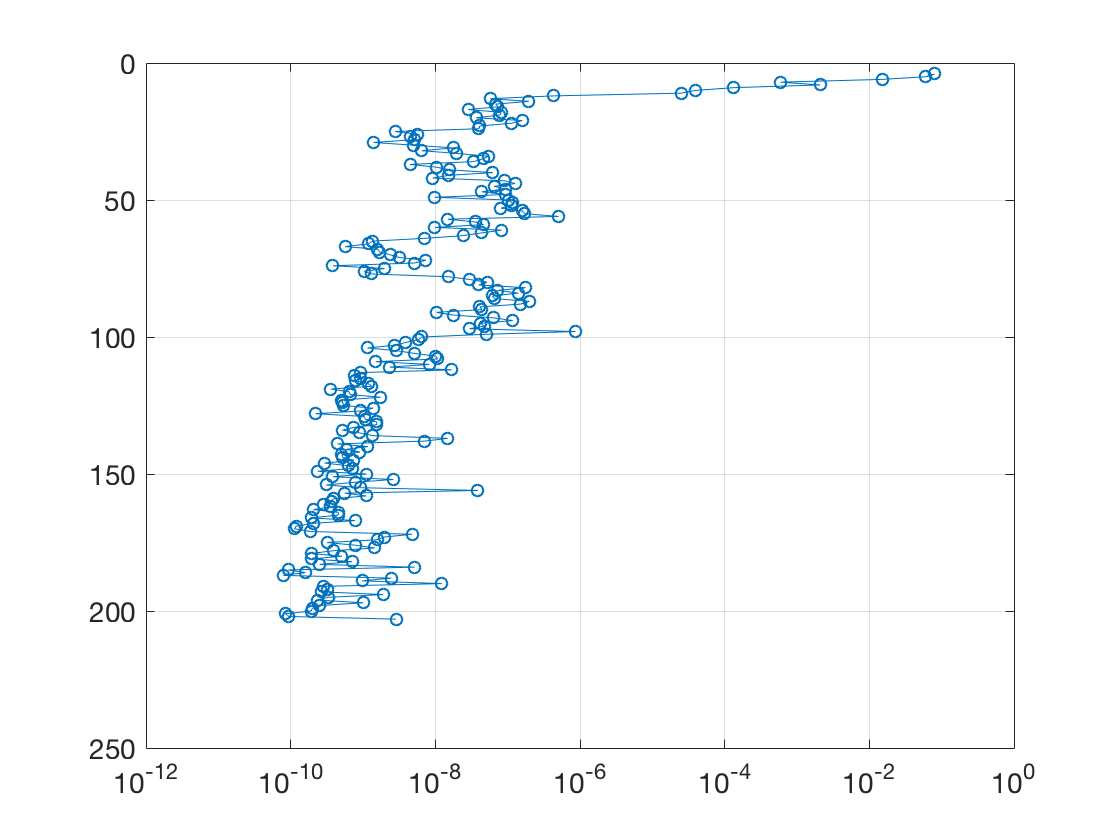

clear ; close all

load('/Users/Andy/Dropbox/ap_share_with_jn/date_from_jim/Tiwe91/mat_Greg_analysis/tw910031.mat')

figure(1);clf
semilogx(avg.EPSILON,avg.P,'o-')
axis ij
grid on

% combine all profiles into a single structure for plotting etc

p_com=0:250; % interp all profiles to this common pressure vector




% loop over all profiles and get variables N2,dtdz,chi,eps so we
% can look at distributions and compare to EQ14

n2=[];
dtdz=[];
chi=[];
eps=[];
datdir='/Users/Andy/Dropbox/ap_share_with_jn/date_from_jim/Tiwe91/mat_Greg_analysis/'

datdir = /Users/Andy/Dropbox/ap_share_with_jn/date_from_jim/Tiwe91/mat_Greg_analysis/

file_list=dir( fullfile( datdir,['tw91*' '*.mat']) );

for ip=1:length(file_list)
    clear avg
    try
    load( fullfile('/Users/Andy/Dropbox/ap_share_with_jn/date_from_jim/Tiwe91/mat_Greg_analysis/',file_list(ip).name ) )
    n2=[n2 ; avg.N2(:) ];
    dtdz=[dtdz ; avg.DTDZ(:)];
    chi=[chi ; avg.CHI(:) ];
    eps=[eps; avg.EPSILON(:) ] ;
    end
    
end % ip

disp('Done')

Done


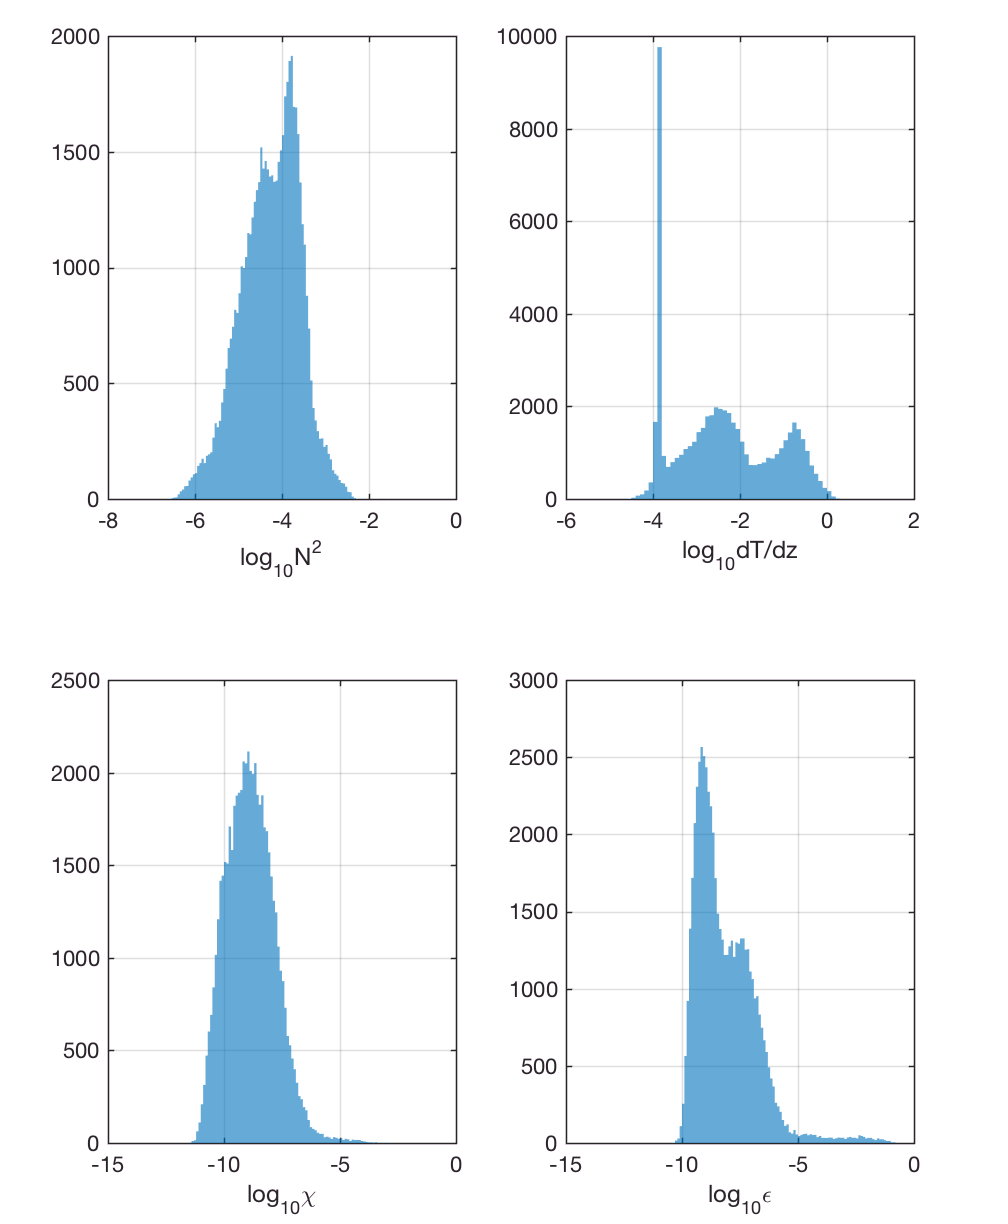

% plot distrbutions of variables

figure(1);clf
agutwocolumn(1)
wysiwyg

subplot(221)
histogram(real(log10(n2(:))),'edgecolor','none')
xlabel('log_{10}N^2')
grid on

subplot(222)
histogram(real(log10(dtdz(:))),'edgecolor','none')
xlabel('log_{10}dT/dz')
grid on

subplot(223)
histogram(log10(chi(:)),'edgecolor','none')
xlabel('log_{10}\chi')
grid on

subplot(224)
histogram(log10(eps(:)),'edgecolor','none')
xlabel('log_{10}\epsilon')
grid on

Next I compare distributions from the TIWE data to the EQ14 data. N2 looks very similar.  dT/dz from TIWE looks a little strange. There are two peaks, and then a sharp spike at very small values which is probably junk. Chi looks similar, with EQ14 being centered at a slightly smaller value. Epsilon looks very similar.

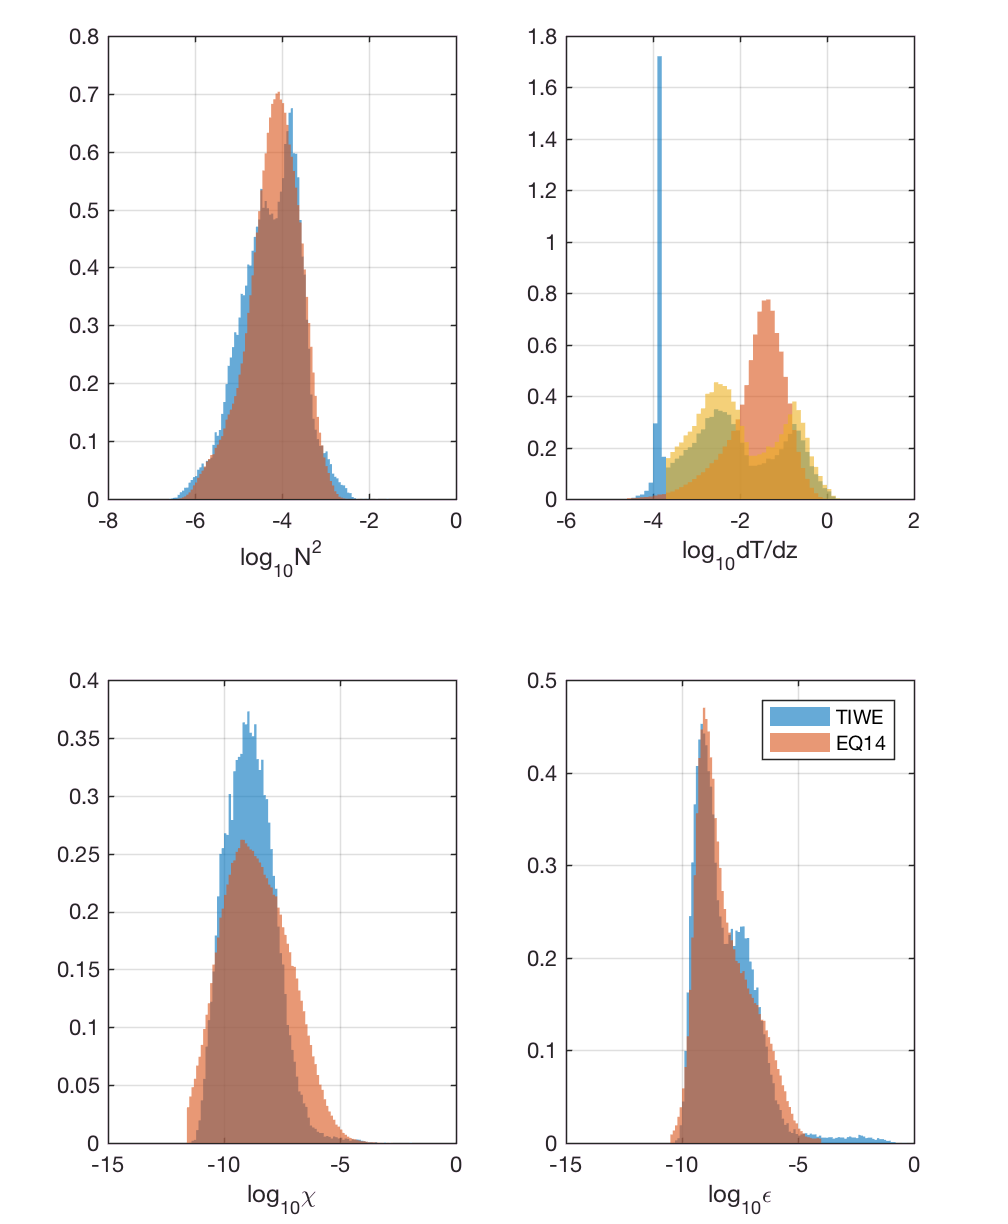

% compare to EQ distributions

dir_base='/Users/Andy/Cruises_Research/ChiPod/Cham_Eq14_Compare/Data/chameleon/processed';
clear cham
load( fullfile( dir_base, '/Cstar=0_01366/sum/eq14_sum.mat') )

Nm='pdf';

figure(1);clf
agutwocolumn(1)
wysiwyg

subplot(221)
h1=histogram(real(log10(n2(:))),'edgecolor','none','Normalization',Nm);
hold on
h2=histogram(real(log10(cham.N2(:))),h1.BinEdges,'edgecolor','none','Normalization',Nm);
xlabel('log_{10}N^2')
grid on

% try removing the weird spike in values near 1e-4
dtdz_2=dtdz;
ib2=find(log10(dtdz_2)<-3.7);
dtdz_2(ib2)=nan;

subplot(222)
h1=histogram(real(log10(dtdz(:))),'edgecolor','none','Normalization',Nm);
hold on
h2=histogram(real(log10(cham.DTDZ(:))),h1.BinEdges,'edgecolor','none','Normalization',Nm);
h3=histogram(real(log10(dtdz_2(:))),h1.BinEdges,'edgecolor','none','Normalization',Nm);
xlabel('log_{10}dT/dz')
grid on

subplot(223)
h1=histogram(log10(chi(:)),'edgecolor','none','Normalization',Nm);
hold on
h2=histogram(real(log10(cham.CHI(:))),h1.BinEdges,'edgecolor','none','Normalization',Nm);
xlabel('log_{10}\chi')
grid on

subplot(224)
h1=histogram(log10(eps(:)),'edgecolor','none','Normalization',Nm);
hold on
h2=histogram(real(log10(cham.EPSILON(:))),h1.BinEdges,'edgecolor','none','Normalization',Nm);

xlabel('log_{10}\epsilon')
grid on
legend([h1 h2],'TIWE','EQ14')

Next I compute gamma from both datasets and compare the distribution. The EQ14 distribution appears to be slightly smaller. The TIWE distribution has a second hump at high values, which I think are just bogus data where dT/dz is really small or something.

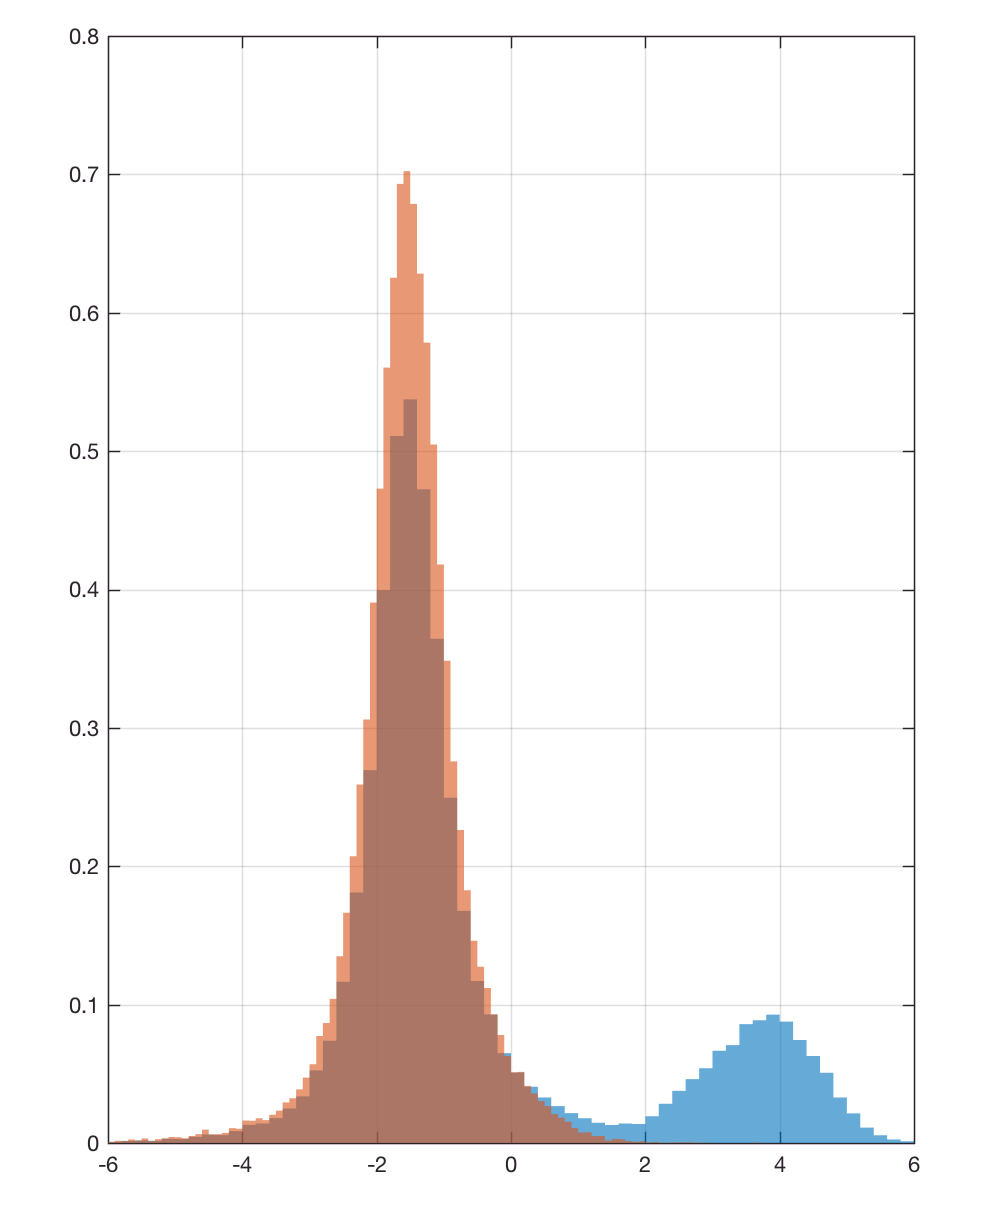

% compute gamma
gam_tiwe=n2 .* chi ./2 ./ eps ./ (dtdz.^2);
gam_tiwe_2=n2 .* chi ./2 ./ eps ./ (dtdz_2.^2);
gam_eq14=cham.N2 .* cham.CHI ./2 ./cham.EPSILON ./(cham.DTDZ.^2);

% plot distributions
figure(1);clf
h1=histogram(real(log10(gam_tiwe(:))),'edgecolor','none','Normalization','pdf');
hold on
h2=histogram(log10(gam_eq14(:)),h1.BinEdges,'edgecolor','none','Normalization','pdf');
%h3=histogram(real(log10(gam_tiwe_2(:))),'edgecolor','none','Normalization','pdf');
grid on
xlim([-6 6])

legend([h1 h2],'tiwe','eq14')

Error using legend>process_inputs (line 526)
Invalid argument. Type 'help legend' for more information.

Error in legend>make_legend (line 303)
[orient,location,position,children,listen,strings,propargs] = process_inputs(ha,argin); %#ok

Error in 

xlabel('log_{10}\Gamma','fontsize',16)


% try identifying overturns/patches in tiwe and compare to the patch data Bill shared
addpath /Users/Andy/Cruises_Research/seawater_ver3_2/
datdir='/Users/Andy/Dropbox/ap_share_with_jn/date_from_jim/Tiwe91/mat_Greg_analysis/'

datdir = /Users/Andy/Dropbox/ap_share_with_jn/date_from_jim/Tiwe91/mat_Greg_analysis/

file_list=dir( fullfile( datdir,['tw91*' '*.mat']) );
dat_sum=[]

dat_sum = []

warning off
for ip=1:length(file_list)
    clear avg
%    try
        load( fullfile('/Users/Andy/Dropbox/ap_share_with_jn/date_from_jim/Tiwe91/mat_Greg_analysis/',file_list(ip).name ) )
        
        % this is 1m binned data ; see if there are any overturns
        
        % below is modified from compute_overturns_discrete_AP.m **
        clear s t p refd lat pden ptmp
        s=avg.S;
        t=avg.T1;
        p=avg.P;
        refd=0;
        lat=1.7;%str2num(head.lat.start);%1.7;%nanmean(head.lat.start)
        
        [pstarts pstops]=IdentifyPatches(s,t,p,lat);
        
        for i=1:length(pstarts)
            dat_sum=[dat_sum ; ip pstarts(i) pstops(i)  ( pstops(i) - pstarts(i) ) ];
        end
        
        %
%    end % try
    
end % ip
warning on

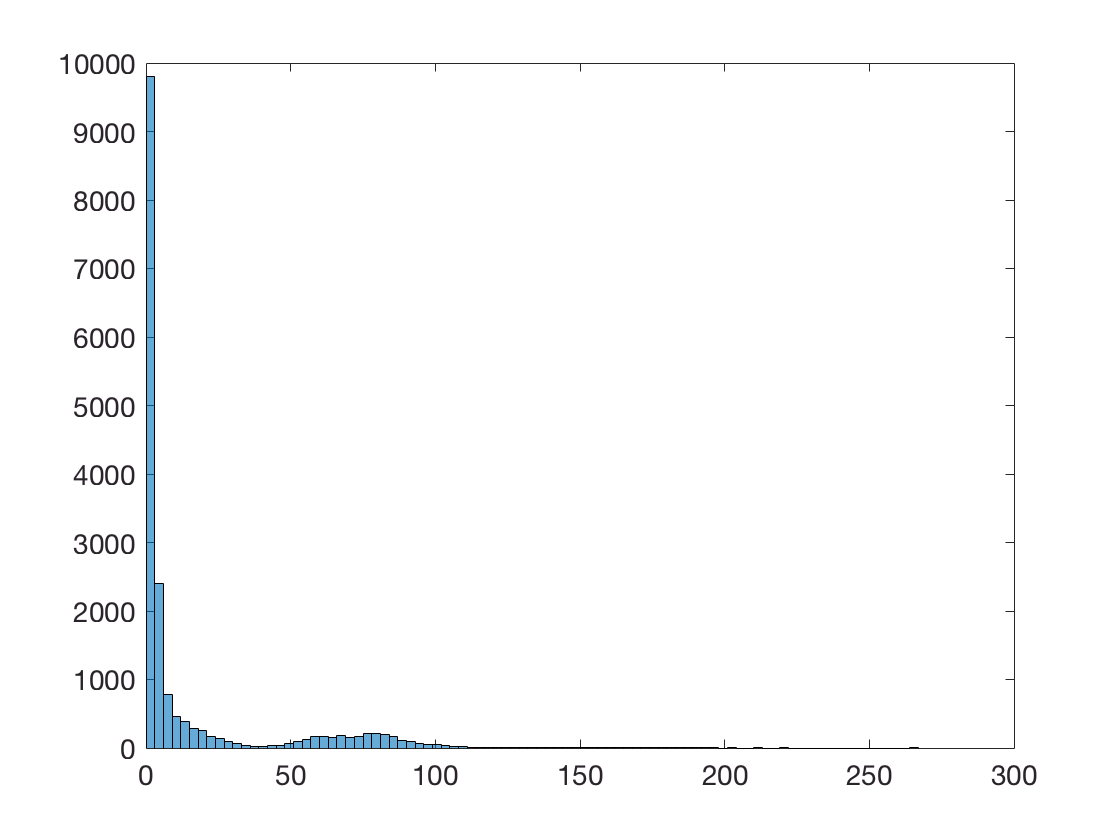

% plot distribution of overturn sizes
figure
histogram(dat_sum(:,4))


% compare to Bill's patch data?




%figure(2);clf
%loglog(chi(:),eps(:),'.')
%scatter(log10(chi(:)), log10(eps(:)),'filled','markerfacealpha',0.2)


%figure(3);clf
%histogram2(log10(chi(ig)),log10(eps(ig)),'DisplayStyle','tile')
%colorbar
%caxis([0 500])
